# Bagged Tree Model Simulation

Test the bagged tree ensemble model with more realistic scenarios using a Monte Carlo simulations. 

## Define directories and load data

% Find base directory
basedir = fileparts(pwd);

% Set data directory
datadir = fullfile(basedir,"data","DataExamplesv2");

% File descriptions
fileDescripts = readtable(fullfile(datadir,"FileDescriptions.xlsx"),'TextType','string');
fileDescripts.AircraftPresent = fileDescripts.AircraftPresent == "Y";
fileDescripts.Contaminated = fileDescripts.Contaminated == "Y";

% Destinate contamination files to use
contaminationFiles = fileDescripts.FileName(fileDescripts.Contaminated);
ncontimations = length(contaminationFiles);
% Destinate signal files to use
signalFiles = fileDescripts.FileName(~fileDescripts.Contaminated);
nsignals = length(signalFiles);

% Set model directory and file
modeldir = fullfile(basedir,"data","Models");
modelfilename = "ModelBaggedTreesDWPT5Lvl.mat";
load(fullfile(modeldir,modelfilename))
% model variable name is mdlBag5lvl
waveletName = 'coif2';
waveletLevels = 5; 

% Set Monte Carlo directory and file
mcfolder = fullfile(basedir,"data","MonteCarlo");
mcfilename = "mcBagged5LvlResults.mat";

% Create pool of MATLAB workers
% tic; parpool('local',4); toc

## Set Monte Carlo parameters

% Number of Monte Carlo iterations
% Use a small number to make sure everything runs without error, then
% change to a large number for the Monte Carlo simulation
% nruns = 100;    % for debugging
nruns = 100000;  % for Monte Carlo simulation

% % Initialize table for Monte Carlo results
% varNames = ["BlockLength","SignalFile","SignalStartIndx","ContaminatedTrue","FracBlockContaminated","ContaminationStartIndx", ... 
%             "ContaminationFile","ContaminationIndx","SNRdB","ContaminatedPred"];
% varTypes = ["double","string","double","logical","double","double", ... 
%             "string","double","double","logical"];
% 
% nvars = length(varNames);
% tmcoutput = table('Size',[nruns nvars],'VariableTypes',varTypes,'VariableNames',varNames);

% Initialize variables for parallel Monte Carlo loop (parfor)
BlockLength = zeros(nruns,1);
SignalFile = strings(nruns,1);
SignalStartIndx = zeros(nruns,1);
ContaminatedTrue = false(nruns,1);
FracBlockContaminated = zeros(nruns,1);
ContaminationStartIndx = zeros(nruns,1);
ContaminationFile = strings(nruns,1);
ContaminationIndx = zeros(nruns,1);
SNRdB = zeros(nruns,1);
ContaminatedPred = false(nruns,1);

## Initialize Monte Carlo simulation

rng(42);    % set random seed

% Set block length
% Record length of audio block in number of points
tblock = 2;     % block length (s)
fs = 51200;     % sampling frequency (Hz)
nblock = tblock*fs;

tic
% Monte Carlo Loop
parfor imc = 1:nruns
    signalFilesloop = signalFiles;
    contaminationFilesloop = contaminationFiles;
    
    BlockLength(imc) = nblock;
    
    % Pick signal file and load
    % One of the 59 signal or ambient audio recording files
    idxsignal = randi(nsignals);
    SignalFile(imc) = signalFilesloop(idxsignal);
    
    x = audioread(fullfile(datadir,signalFilesloop(idxsignal)))';
    
    % Pick portion of signal
    % Select one block of data from the signal
    idxStart = randi(length(x)-nblock);
    SignalStartIndx(imc) = idxStart;
    
    x = x(idxStart:idxStart+nblock-1);
    
    % Random contamination
    contaminatedTrue = logical(randi(2)-1);
    ContaminatedTrue(imc) = contaminatedTrue;
    
    if contaminatedTrue
        % Pick portion of data block contaminated
        % Valid values from 25% to 100%
        fracContaminated = (3*rand(1) + 1)/4;
        nContaminated = round(nblock*fracContaminated);
        FracBlockContaminated(imc) = fracContaminated;
        
        % Pick start of contamination in block
        contaminationStart = randi(length(x)-nContaminated);
        ContaminationStartIndx(imc) = contaminationStart;
        
        % Pick contamination file
        idxcontamination = randi(ncontimations);
        ContaminationFile(imc) = contaminationFilesloop(idxcontamination);
        
        n = audioread(fullfile(datadir,contaminationFilesloop(idxcontamination)))';
        
        % Pick portion of contamination signal to use
        idxCont = randi(length(n)-nContaminated);
        ContaminationIndx(imc) = idxCont;
        
        n = n(idxCont:idxCont+nContaminated-1);
        
        % Pick SNR and contaminated the signal
        % Valid values from 6 dB to 18 dB
        snrdB = 12*rand(1) + 6;
        SNRdB(imc) = snrdB;
        
        % Pick portion of x to contaminate
        cIdx = (1:nContaminated) + randi(length(x)-nContaminated+1) - 1;
        y = x(cIdx);
        
        y = addNoise(y,n,snrdB);
        
        % Construct contaminated signal
        x(cIdx) = y;
    end
    
    % Generated features
    % Insert function to compute features
    xfeatures = dwptFeatures(x,'WaveletName',waveletName,'WaveletLevel',waveletLevels);
    
    % Make prediction
    % Insert function to make prediction from features
    % Must be logical value
    contaminatedPred = mdlBag5lvl.predictFcn(xfeatures);
    ContaminatedPred(imc) = contaminatedPred;
end
toc

Elapsed time is 62.357264 seconds.


% Construct output table
tmcoutput = table(BlockLength,SignalFile,SignalStartIndx,ContaminatedTrue,FracBlockContaminated,ContaminationStartIndx, ... 
            ContaminationFile,ContaminationIndx,SNRdB,ContaminatedPred);

% Score overall simulation
[acc,fpr,fnr,f1] = scoreModel(tmcoutput.ContaminatedTrue,tmcoutput.ContaminatedPred);

## Save simulation results


Variables:

    BlockLength: 100×1 double

        Values:

            Min         1.024e+05  
            Median      1.024e+05  
            Max         1.024e+05  

    SignalFile: 100×1 string

    SignalStartIndx: 100×1 double

        Values:

            Min                3783    
            Median       7.7116e+05    
            Max          7.2946e+06    

    ContaminatedTrue: 100×1 logical

        Values:

            True             47        
            False            53        

    FracBlockContaminated: 100×1 double

        Values:

            Min                     0        
            Median                  0        
            Max               0.99979        

    ContaminationStartIndx: 100×1 double

        Values:

            Min                    0          
            Median                 0          
            Max                60697    


Variables:

    BlockLength: 47×1 double

        Values:

            Min         1.024e+05  
            Median      1.024e+05  
            Max         1.024e+05  

    SignalFile: 47×1 string

    SignalStartIndx: 47×1 double

        Values:

            Min               24808    
            Median       7.9589e+05    
            Max          7.2946e+06    

    ContaminatedTrue: 47×1 logical

        Values:

            True             47        
            False             0        

    FracBlockContaminated: 47×1 double

        Values:

            Min               0.26244        
            Median            0.66003        
            Max               0.99979        

    ContaminationStartIndx: 47×1 double

        Values:

            Min                   22          
            Median             12418          
            Max                60697          

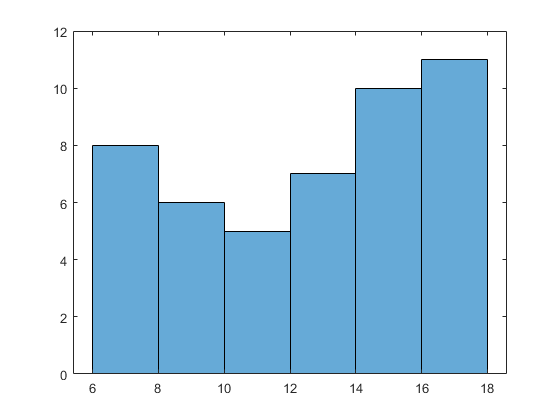

% Save Monte Carlo results
save(fullfile(mcfolder,mcfilename),'tmcoutput')